# Lagrange-Interpolation

Bestimmung des Lagrange-Interpolationspolynoms

                            
$$P(f|x_0,\ldots,x_n)(x_j)=f(x_j), \quad j=0,\ldots,n.$$


Bespiele:

1) $f(x)=\sin \left(\frac{1}{x^2+0.1}\right),\quad  x \in I=[-2,2] \quad \text{(glatte Funktion)}$

2) $f(x)=\sin(\pi x), \quad x \in I=[-2,2] ~~\text{(periodisch)}$

3) $f(x)=\frac{1}{1+x^2}, \quad x \in I=[-5,5]~~\text{(Runge Beispiel)}$

4) $f(x)=|x|, \quad x \in I=[-2,2] ~~\text{(nicht glatt)}
$

Im graphischen Fenster gibt es folgende Optionen:

-    **Funktion**: man kann (unter **Beispiele**) eine der obenstehenden Funktionen wählen.       

-    **Grad**: man kann den Polynomgrad ändern.

-    **Stützstellen**: äquidistant oder Tschebyscheff-Stützstellen (siehe Buch).

-    **Teilintervalle**: die Anzahl der Teilintervalle des Gesamtintervalls, auf denen die Interpolation bestimmt wird.

-   ** Intervall**: man kann das Interpolationsintervall $I$ anpassen.  

# Aktivität:

Drücken Sie "Run" bzw. F5, um die Demo zu starten. Wählen Sie unterschiedliche Beispiele und untersuchen Sie das Verhalten der Interpolationspolynome abhängig vom Polynomgrad, Typ der Stützstellen (äquidistant oder Tschebyscheff) und Anzahl der Teilintervalle.

Unterstehendes MATLAB-Program **TCM_polyint** wurde an der Uni-Stuttgart im Rahmen des Projektes ``Teaching Calculus mit MATLAB'' entwickelt, siehe [https://pnp.mathematik.uni-stuttgart.de/imng/TCM/.](https://pnp.mathematik.uni-stuttgart.de/imng/TCM/.)

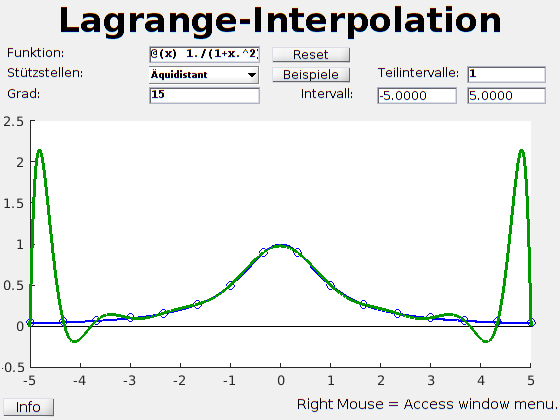

TCM_polyint

function TCM_polyint

% Authors: Florian Martin, Lars von Wolff
% Last updated: 27.06.2016

% Initialize data
TCM_Data.points = [];
TCM_Data.poly = [];
TCM_Data.valerr = [];
TCM_Data.V = [];
TCM_Data.fun = 0;
TCM_Data.maxerr = NaN;
TCM_Data.measerr=0;
TCM_Data.n = 0;

% Do not delete these Variables
TCM_Data.plot_window = [-2 2 -1.5 1.5];
TCM_Data.LmbMenuString = '';
TCM_Data.examples = {'1) glatte Funktion','2) periodische Funktion','3) Runge-Funktion','4) nicht-glatte Funktion'};

% Layout:
% ---------------------------------------
% |               Title                 |
% | ------------ --------- ------------ |
% | | Settings | |Buttons| | Feedback | |
% | ------------ --------- ------------ |
% | ----------------------------------- |
% | |           Axis (Plot)           | |
% | ----------------------------------- |
% | Info-Button         Hint            |
% ---------------------------------------
% Initialize Layout:
TCM_UI.TitleHeightMin = 10;        % minimal height of the title
TCM_UI.TitleHeightMax = 32;        % maximal height of the title
TCM_UI.HintHeightMin = 8;          % minimal height of the hint
TCM_UI.HintHeightMax = 15;         % maximal height of the hint
TCM_UI.SettingsHeightMin = 30;     % minimal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsHeightMax = 70;    % maximal height of the feedback, buttons and 
                                   % setting panel
TCM_UI.SettingsRatio = 4.5;          % aspect ratio of the settings  
                                   % (increase if more settings needed)
TCM_UI.ButtonsRatio = 1.4;         % aspect ratio of the Buttons panel
TCM_UI.FeedbackRatio = 3.4;        % aspect ratio of the feedback
TCM_UI.AxisHeightTarget = 0.3;    % desired fraction of figure 
                                   % used for the plot
TCM_UI.InfoPortion = 1/10;          % Portion of the Info Button in the last  
                                   % line 
                                   
TCM_UI.Title = 'Lagrange-Interpolation';
TCM_UI.mono = get(0,'FixedWidthFontName');
% Strings for generating the information window
TCM_UI.Web = 'http://www.mathematics-online.org/inhalt/aussage/aussage1';
    
CreateUI();

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Settings %%%%%%%%%%%%%%%%%%%%
% Popup for Function
TCM_UI.funtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.70,.5,.30],...
	'String','Funktion:',...
	'Style','text');

% Input for Function
TCM_UI.funinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.55,.70,.42,.30],...
	'String','',...
	'Style','edit',...
	'Callback',@function_update);

% Text for Interpolation Points
TCM_UI.pointtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.35,.5,.30],...
	'String','Stützstellen:',...
	'Style','text');

% Popup for Interpolation Points
TCM_UI.pointpopup=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.5,...
        'HorizontalAlignment','left', ...
	'Position',[.55,.35,.42,.30],...
	'String',{'','Äquidistant','Tschebyscheff'},...
	'Style','popup','Callback',@interp_mode);

% Text for Number of Points
TCM_UI.numtext = uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.01,.0,.5,.30],...
	'String','Grad:',...
	'Style','text');

% Number of Points
TCM_UI.numinput=uicontrol('Units','normalized', 'Parent',TCM_UI.settingspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.55,.0,.42,.30],...
	'String','0','enable','off',...
	'Style','edit','Callback',@restart);

%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Buttons Panel %%%%%%%%%%%%%%%%%%%%
% Reset-Button
TCM_UI.restart=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Reset', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.70,.98,.30], ...
	'Callback',@restart,...
	'Style','pushbutton');

% Example button
TCM_UI.examples=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
	'BackgroundColor',get(gcf,'Color'), ...
	'String','Beispiele', ...
    'FontUnits','normalized','FontSize',0.7,...
	'Position',[.01,.35,.98,.30], 'Callback',@OpenExampleMenu,...
	'Style','pushbutton');

% Text for 'Interval'
TCM_UI.l2val=uicontrol('Units','normalized','Parent',TCM_UI.buttonspanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'HorizontalAlignment','left', ...
        'FontUnits','normalized','FontSize',0.7,...
	'Position',[.36,.0,.9,.30],...
	'String','Intervall:',...
	'Style','text');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Feedback %%%%%%%%%%%%%%%%%%%%

% Text for Measurement Error
TCM_UI.measerrtext = uicontrol('Units','normalized', 'Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.1,.35,.5,.30],...
	'String','Meas. Err.:',...
        'Visible','off',...
	'Style','text');

% Number of Points
TCM_UI.measerrinput=uicontrol('Units','normalized', 'Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.55,.35,.40,.30],...
	'String','0','enable','on',...
    'Visible','off',...
	'Style','edit','Callback',@change_measerr);

% Text for Measurement Error
TCM_UI.subintertext = uicontrol('Units','normalized', 'Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.67,...
        'HorizontalAlignment','left', ...
	'Position',[.1,.35,.5,.30],...
	'String','Teilintervalle:',...
	'Style','text');

% Number of Points
TCM_UI.subinterinput=uicontrol('Units','normalized', 'Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontWeight','bold',...
        'FontUnits','normalized','FontSize',0.65,'FontName',TCM_UI.mono,...
        'HorizontalAlignment','left', ...
	'Position',[.55,.35,.40,.30],...
	'String','1','enable','on',...
	'Style','edit','Callback',@change_subinter);

% Left end of Window
TCM_UI.leftinput=uicontrol('Units','normalized', 'Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.7,...
        'HorizontalAlignment','left', ...
	'Position',[.1,.0,.4,.30],...
    'String',sprintf('%f',TCM_Data.plot_window(1)),...
	'Style','edit','Callback',@plotsize_update);

% Right end of Window
TCM_UI.rightinput=uicontrol('Units','normalized', 'Parent',TCM_UI.feedbackpanel, ...
        'BackgroundColor',get(gcf,'Color'), ...
        'FontUnits','normalized','FontSize',0.7,...
        'HorizontalAlignment','left', ...
	'Position',[.55,.0,.4,.30],...
	'String',sprintf('%f',TCM_Data.plot_window(2)),...
	'Style','edit','Callback',@plotsize_update);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% UI-Elements in Axis %%%%%%%%%%%%%%%%%%%%%%%%
% Axis for Function display
TCM_UI.ax=axes('Position',[.05,.1,.9,.85],'Parent',TCM_UI.axispanel);
axis(TCM_UI.ax,'equal');
TCM_UI.modification = uicontextmenu('Callback',@reset_zoom_limits); 
TCM_UI.mpan = uimenu('Parent',TCM_UI.modification,'Label','Enable pan',...
        'Callback',@axis_context);
TCM_UI.mzoomi = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom in',...
    'Callback',@axis_context); 
TCM_UI.mzoomo = uimenu('Parent',TCM_UI.modification,'Label','Enable zoom out',...
        'Callback',@axis_context); 
TCM_UI.ax.UIContextMenu = TCM_UI.modification;

% functions for smoothless zooming and panning
panfun = pan(TCM_UI.fig);
panfun.UIContextMenu = TCM_UI.modification;
set(panfun,'ActionPostCallback',@pan_modify);
zoomfun = zoom(TCM_UI.fig);
zoomfun.UIContextMenu = TCM_UI.modification; 
set(zoomfun,'ActionPostCallback',@zoom_modify);
set(zoomfun,'ButtonDownFilter',@set_zoom_limits);
set(zoomfun,'RightClickAction','PostContextMenu');
set(findall(TCM_UI.fig,'tag','Exploration.Pan'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomOut'),'enable','off');
set(findall(TCM_UI.fig,'tag','Exploration.ZoomIn'),'enable','off');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Start the program %%%%%%%%%%%%%%%%%%%%%%%%%%
changeexample(3);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%% Callback functions %%%%%%%%%%%%%%%%%%%%%%%%%%%
function interp_mode(varargin)
if(strcmp(TCM_UI.numinput.Enable, 'off') && TCM_UI.pointpopup.Value > 1)
    set(TCM_UI.numinput,'String','5');
end
restart;
end

% new function input
function function_update(varargin)
TCM_Data.fun = eval(get(TCM_UI.funinput,'String'));
x = linspace(-2,+2);
f = TCM_Data.fun(x); f(isinf(f)) = 0;
h = max(f)-min(f);
TCM_Data.plot_window = [x(1) x(end) min(f)-h/8 max(f)+h/8];
TCM_Data.plot_window(3) = min(TCM_Data.plot_window(3),-1);
TCM_Data.plot_window(4) = max(TCM_Data.plot_window(4),1);
restart;
end

% Update Left or Right end of Plot
function plotsize_update(varargin)
TCM_Data.plot_window(1) = min(str2double(TCM_UI.leftinput.String),...
                              str2double(TCM_UI.rightinput.String));
TCM_Data.plot_window(2) = max(str2double(TCM_UI.leftinput.String),...
                              str2double(TCM_UI.rightinput.String));
myplot;
end

% Update Left or Right end of Plot
function change_measerr(varargin)
TCM_Data.measerr = str2double(TCM_UI.measerrinput.String);
calc_polyint;
myplot;
end

function change_subinter(varargin)
calc_points;
calc_polyint;
myplot;
end

% refresh all data from UI
function restart(varargin)
% Disable Zoom/Pan
window_disable.Label = 'Disable pan';
axis_context(window_disable);
% Reset the calculated/set points and recalculate them, Update Hinttext
TCM_Data.points = [];
calc_points;
% Update UI
if TCM_UI.pointpopup.Value == 1
    set(TCM_UI.numinput,'enable','off');
else
    set(TCM_UI.numinput,'enable','on');
end
% Update Plot
calc_polyint;
myplot;
end

% mouse button pressed 
function myDownfct(varargin)
x = get(TCM_UI.ax,'xlim');
y = get(TCM_UI.ax,'ylim');
if strcmp(get(TCM_UI.fig,'SelectionType'),'normal') && (TCM_UI.pointpopup.Value == 1)
  newpoint=get(TCM_UI.ax,'CurrentPoint');
  if newpoint(1) < x(1) || newpoint(1) > x(2) || ...
          newpoint(3) < y(1) || newpoint(3) > y(2)
      return;
  end
  TCM_Data.points = [TCM_Data.points, newpoint(1)];
  calc_points;
  calc_polyint;
  myplot;
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% kernel functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

% plot function
function myplot
cla(TCM_UI.ax, 'reset'); 
hold(TCM_UI.ax, 'on');
% evaluating and plotting of the input function on a square containing the
% current window for smoothless panning and zooming
evalsubs=ceil(1000/TCM_Data.m);
evalplot = evalsubs * TCM_Data.m; 
evalall=evalplot * 3;

h = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
x = linspace(TCM_Data.plot_window(1)-h,TCM_Data.plot_window(2)+h,evalall);

fx = x;
% plot of the interpolation points and the interpolating polynomial
if numel(TCM_Data.points) > 0
    for i=1:numel(TCM_Data.points)
        plot(TCM_UI.ax,TCM_Data.points(i),TCM_Data.fun(TCM_Data.points(i)),'oblue');
    end
    
    px=x;
    px(1:evalplot ) = polyval(TCM_Data.poly(1,:),x(1:evalplot));
    fx(1:evalplot ) = TCM_Data.fun(x(1:evalplot));
    
    start=evalplot;
    for j=1:TCM_Data.m
       
        px(start+1:start+evalsubs) = polyval(TCM_Data.poly(j,:),x(start+1:start+evalsubs));
        fx(start+1:start+evalsubs) = TCM_Data.fun(x(start+1:start+evalsubs));
        start = start+evalsubs;
    end
    px(2*evalplot:evalall ) = polyval(TCM_Data.poly(TCM_Data.m,:),x(2*evalplot:evalall));
    fx(2*evalplot:evalall ) = TCM_Data.fun(x(2*evalplot:evalall));
    
    
    plot(TCM_UI.ax,x,fx,'-','linewidth',2,'color',[0,0,.99]); 
    plot(TCM_UI.ax,[x(1) x(end)],[0 0],'black');
    
    plot(TCM_UI.ax,x,px,'-','linewidth',2.5,'Color',[0,.6,0]);
else
    TCM_Data.maxerr = [];
end
set(TCM_UI.leftinput,'String',sprintf('%.4f',TCM_Data.plot_window(1)));
set(TCM_UI.rightinput,'String',sprintf('%.4f',TCM_Data.plot_window(2)));
SetWindowLimits
end

% Calculate the interpolating Polynomial
function calc_polyint
TCM_Data.poly=zeros(TCM_Data.m,TCM_Data.n+1);

for j=1:TCM_Data.m
    if numel(TCM_Data.points(j,:)) > 0
        ydata = zeros(1,TCM_Data.n+1);
  
        for i=1:TCM_Data.n+1
            ydata(i) = TCM_Data.fun(TCM_Data.points(j,i));
        end
        w = warning;
        warning('off','MATLAB:polyfit:RepeatedPointsOrRescale'); % Do not display this warning
        TCM_Data.poly(j,:) = polyfit(TCM_Data.points(j,:),ydata,TCM_Data.n);
        warning(w); 
    else
        TCM_Data.poly = [];
    end
end
end

% Calculate the interpolation points (and update the UI)
function calc_points

TCM_Data.n=str2double(TCM_UI.numinput.String);
numpoints = TCM_Data.n+1;

TCM_Data.m=str2double(TCM_UI.subinterinput.String);

TCM_Data.points = zeros(TCM_Data.m,TCM_Data.n+1);

h= (TCM_Data.plot_window(2)-TCM_Data.plot_window(1))/TCM_Data.m;

a_m = TCM_Data.plot_window(1);

for j=1:TCM_Data.m
    switch(TCM_UI.pointpopup.Value)
        case 2
            TCM_Data.points(j,:) = linspace(a_m,a_m+h,numpoints);
        case 3
            l=(2*(1:numpoints)-1)*pi/(2*numpoints);
            TCM_Data.points(j,:) = a_m + ...
                h*0.5*(1+cos(l));
    end
    a_m = a_m + h;
end
if(numel(TCM_Data.points)>0)
    set(TCM_UI.numinput,'String',num2str(TCM_Data.n));
else
    set(TCM_UI.numinput,'String','-');
end
end

% Update the Hinttext
function UpdateHinttext
if TCM_UI.pointpopup.Value == 1
    LmbString = 'Left Mouse = Add interpolation point. ';
else
    LmbString = '';
end
if(numel(TCM_Data.LmbMenuString) == 0)
    set(TCM_UI.hinttext,'String',[LmbString 'Right Mouse = Access window menu.']);
else
    set(TCM_UI.hinttext,'String',[TCM_Data.LmbMenuString 'Right Mouse = Access window menu.']);
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% example functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

function CreateExampleMenu
TCM_UI.UICexamples = uicontextmenu;
for i=1:numel(TCM_Data.examples)
    uimenu('Parent',TCM_UI.UICexamples,'Label',TCM_Data.examples{i},'Callback',{@changeexample,i});
end
end

function OpenExampleMenu(varargin)
TCM_UI.examples.Units = 'pixels';
TCM_UI.buttonspanel.Units = 'pixels';
TCM_UI.UICexamples.Position = TCM_UI.examples.Position(1:2) + TCM_UI.buttonspanel.Position(1:2);
TCM_UI.examples.Units = 'normalized';
TCM_UI.buttonspanel.Units = 'points';
TCM_UI.UICexamples.Visible = 'on';
end
 
function y = P(x)
    y=polyval(TCM_Data.a(1:TCM_Data.n),x);
end    
              
function changeexample(varargin)  
switch varargin{numel(varargin)}
    
    case 1
        TCM_UI.funinput.String = '@(x) sin(1./(x.^2+0.1))';
        TCM_UI.pointpopup.Value = 2;
        TCM_UI.numinput.String = '10';
        TCM_Data.plot_window = [-2 2   -1.5 2];
    case 2
        TCM_UI.funinput.String = '@(x) sin(pi*x)';
        TCM_UI.pointpopup.Value = 2;
        TCM_UI.numinput.String = '4';
        TCM_Data.plot_window = [-2 2 -1.5 1.5];
    case 3
        TCM_UI.funinput.String = '@(x) 1./(1+x.^2)';
        TCM_UI.pointpopup.Value = 2;
        TCM_UI.numinput.String = '15';
        TCM_Data.plot_window = [-5 5 -0.5 2.5];
    case 4
        TCM_UI.funinput.String = '@(x) abs(x)';
        TCM_UI.pointpopup.Value = 2;
        TCM_UI.numinput.String = '10';
        TCM_Data.plot_window = [-2 2 -0.5 2.5];
end
TCM_Data.fun = eval(get(TCM_UI.funinput,'String'));
restart;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% zoom functions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% function for updating the internal plot window
function zoom_modify(varargin)
if max(abs(TCM_Data.plot_window-axis(TCM_UI.ax)))< 10^-10
    ZoomOut;
end
pan_modify;
end

function pan_modify(varargin)
TCM_Data.plot_window = axis(TCM_UI.ax);
myplot;
end

% functions for proper zooming in (prevent double-click zoom out)
function [flag] = set_zoom_limits(varargin)
if(strcmp(TCM_UI.fig.SelectionType,'open'))
    flag = true;
else
    flag = false;
end
end

function reset_zoom_limits(varargin)
SetWindowLimits;
end

% handling the axis context menu
function axis_context(varargin)
zoom(TCM_UI.fig, 'off'); pan(TCM_UI.fig, 'off');
mode_strings = {'pan','zoom in','zoom out'};
status_strings = {'Enable ','Disable '};
switch varargin{1}.Label(1:7)
    case 'Enable '
        mode = strcmp(varargin{1}.Label(8:end),mode_strings);
        TCM_Data.LmbMenuString = ['Left Mouse = ' mode_strings{mode} ' the window. '];
        set(TCM_UI.mpan,'Label',horzcat(status_strings{mode(1)+1},mode_strings{1}));
        set(TCM_UI.mzoomi,'Label',horzcat(status_strings{mode(2)+1},mode_strings{2}));
        set(TCM_UI.mzoomo,'Label',horzcat(status_strings{mode(3)+1},mode_strings{3}));
        split_mode = strsplit(mode_strings{mode},' ');
        if numel(split_mode) == 1
            pan(TCM_UI.fig, 'on');
        else
            zoomh = zoom(TCM_UI.fig);
            zoomh.Enable = 'on';
            zoomh.Direction = split_mode{2};
        end
    case 'Disable'
        TCM_Data.LmbMenuString = '';
        set(TCM_UI.mpan,'Label','Enable pan');
        set(TCM_UI.mzoomi,'Label','Enable zoom in');
        set(TCM_UI.mzoomo,'Label','Enable zoom out');     
end
UpdateHinttext;
end

function SetWindowLimits
ZoomOut;
xlim(TCM_UI.ax,[TCM_Data.plot_window(1) TCM_Data.plot_window(2)]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3) TCM_Data.plot_window(4)]);
end

function ZoomOut
hx = TCM_Data.plot_window(2) - TCM_Data.plot_window(1);
hy = TCM_Data.plot_window(4) - TCM_Data.plot_window(3);
xlim(TCM_UI.ax,[TCM_Data.plot_window(1)-hx/2 TCM_Data.plot_window(2)+hx/2]);
ylim(TCM_UI.ax,[TCM_Data.plot_window(3)-hy/2 TCM_Data.plot_window(4)+hy/2]);
zoom(TCM_UI.fig, 'reset');
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% layout functions %%%%%%%%%%%%%%%%%%%%%%%%%%%

% functions for creating the different UI-Parts and managing the resize of
% the window
function CreateUI
TCM_UI.fig = figure('Visible','off', 'Units','points','Toolbar','none',...
    'SizeChangedFcn',@calculate_layout, 'WindowButtonDownFcn',@myDownfct,...
    'numbertitle','off','name',TCM_UI.Title);
TCM_UI.titletext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
	'HorizontalAlignment','center',  'FontWeight','bold', ...
    'FontUnits','normalized',        'FontSize',0.8,...
	'String',TCM_UI.Title,        'Style','text');
TCM_UI.hinttext = uicontrol('Units','points','BackgroundColor',TCM_UI.fig.Color, ...
    'HorizontalAlignment','right',...
    'FontUnits','normalized',        'FontSize',0.7,...
	'String','','Style','text');
TCM_UI.infobutton=uicontrol('Units','points', ...
	'BackgroundColor',TCM_UI.fig.Color, ...
	'String','Info', 'HorizontalAlignment','left',...
    'FontUnits','normalized','FontSize',0.7,...
	'Callback',@information,'Style','pushbutton');
TCM_UI.feedbackpanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.buttonspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.settingspanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
TCM_UI.axispanel = uipanel('Units','points','BackgroundColor',TCM_UI.fig.Color,'BorderType','none');
CreateExampleMenu
TCM_UI.fig.Visible= 'on';
end


function calculate_layout(varargin) 
figpos = TCM_UI.fig.Position;
WMax = TCM_UI.SettingsHeightMax*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
WMin = TCM_UI.SettingsHeightMin*(TCM_UI.SettingsRatio + TCM_UI.FeedbackRatio + TCM_UI.ButtonsRatio);
HMax = TCM_UI.TitleHeightMax + TCM_UI.HintHeightMax;
HMin = TCM_UI.TitleHeightMin + TCM_UI.HintHeightMin;

wratio = max(0,min(1,(min(figpos(3),1.3*figpos(4))-WMin)/(WMax-WMin)));
XCoords = [1,0,0,0,0,0,0,figpos(3)];
SWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.SettingsRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.SettingsRatio;
BWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.ButtonsRatio...        
    + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.ButtonsRatio; 
FWidth =      wratio*TCM_UI.SettingsHeightMax*TCM_UI.FeedbackRatio...
        + (1-wratio)*TCM_UI.SettingsHeightMin*TCM_UI.FeedbackRatio; 
RemWidth = figpos(3)-3-SWidth-FWidth-BWidth;
XCoords(2) = max(1,0.3*RemWidth);
XCoords(3) = XCoords(2) + 1 + SWidth;
XCoords(4) = XCoords(3) + max(0,0.2*RemWidth);
XCoords(5) = XCoords(4) + 1 + BWidth;
XCoords(6) = XCoords(5) + max(0,0.2*RemWidth);
XCoords(7) = XCoords(6) + 1 + FWidth;
SHeight = wratio*TCM_UI.SettingsHeightMax + (1-wratio)*TCM_UI.SettingsHeightMin;
if(HMin > min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 0;
elseif(HMax <  min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)
    hratio = 1;
else
    hratio = (( min(figpos(4),0.9*figpos(3))*(1-TCM_UI.AxisHeightTarget)-5-SHeight)  -HMin)/(HMax-HMin);
end
YCoords = [1,0,0,0,figpos(4)-1];
YCoords(2) = YCoords(1) + 1 + hratio*TCM_UI.HintHeightMax     + (1-hratio)*TCM_UI.HintHeightMin;
YCoords(4) = YCoords(5) - 1 - hratio*TCM_UI.TitleHeightMax    - (1-hratio)*TCM_UI.TitleHeightMin;
YCoords(3) = YCoords(4) - 1 - SHeight;
TCM_UI.titletext.Position =     [XCoords(1)+1,  YCoords(4)+1,  XCoords(8)-XCoords(1)-1,  YCoords(5)-YCoords(4)-1];
TCM_UI.settingspanel.Position = [XCoords(2)+1,  YCoords(3)+1,  XCoords(3)-XCoords(2)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.buttonspanel.Position =  [XCoords(4)+1,  YCoords(3)+1,  XCoords(5)-XCoords(4)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.feedbackpanel.Position = [XCoords(6)+1,  YCoords(3)+1,  XCoords(7)-XCoords(6)-1,  YCoords(4)-YCoords(3)-1];
TCM_UI.axispanel.Position =     [XCoords(1)+1,  YCoords(2)+1,  XCoords(8)-XCoords(1)-1,  max(0,YCoords(3)-YCoords(2)-1)];
TmpXCoord = TCM_UI.InfoPortion*(XCoords(8)-XCoords(1)-1);
TCM_UI.infobutton.Position =    [XCoords(1)+1,  YCoords(1)+1,  TmpXCoord-XCoords(1)-1,   YCoords(2)-YCoords(1)-1];
TCM_UI.hinttext.Position =      [TmpXCoord+1,   YCoords(1)+1,  XCoords(8)-TmpXCoord-1,   YCoords(2)-YCoords(1)-1];
end

% function for opening the information webpage
function information(varargin)
pos = TCM_UI.fig.OuterPosition;
infodialog = dialog('Name','Information','Units','points',...
    'OuterPosition',[pos(1)+pos(3)/4 pos(2)+pos(4)/4 pos(3)/2 pos(4)/2]);
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.67,...
        'HorizontalAlignment','center', 'Position',[.01,.6,.98,.15],...
	'String','Mathematics Online Link', 'Style','text',...
    'ForegroundColor','blue','ButtonDownFcn',@linkfun,...
    'Enable','inactive');
uicontrol('Units','normalized', 'Parent',infodialog, ...
        'FontUnits','normalized', 'FontSize',0.4,...
        'HorizontalAlignment','center', 'Position',[.01,.4,.98,.15],...
	'String',{horzcat('Created by ',TCM_UI.Author,'.');horzcat('Version: ',TCM_UI.Date)} , 'Style','text');
end

function linkfun(varargin)
web(TCM_UI.Web)
end


end